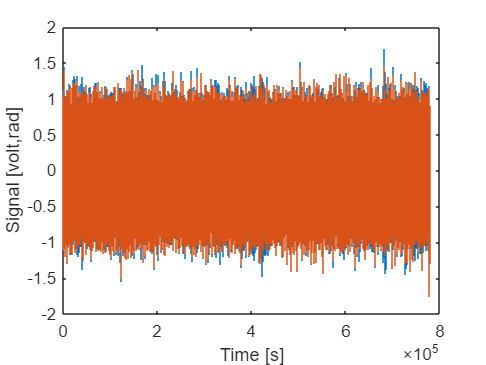

clear all; close all
%load("Data\experiment_26_3.mat")
%load("Data\experiment_26_3_LOADSIDE.mat")
load('Data\nieuwe_setup_gain_0_2.mat')
%load('Data\open_loop_v1000.mat')

%load('Data\loadsidefrf_v2.mat')
%u = measurement(:,2)
%d = measurement(:,1)

%removing useless data 
N_trash = 20e3; 
u = u(N_trash:end);
d = d(N_trash:end);

% Plot the measurement
figure(); clf();
stairs(u); hold on; stairs(d);
xlabel('Time [s]'); ylabel('Signal [volt,rad]');
hold off


%data analysis
fs = 4000 %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04

max_freq = log10(fs/2) 

max_freq = 3.3010

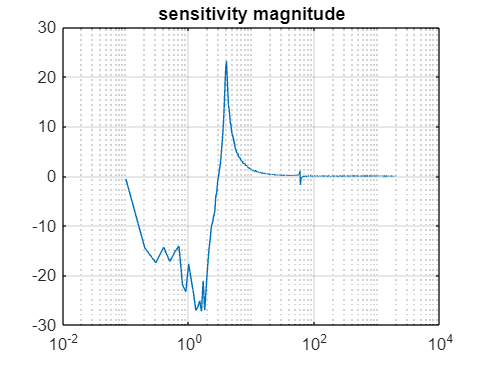

%t_end = N_samples/fs


%window settings
min_freq = 0.1; %[Hz/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize/stepsize); %window size in data points 
n_overlap = round(nfft/4);

%Tf estimate
[Sud, F] = tfestimate(d,u,hann(nfft),n_overlap,nfft,fs); %cross spectral power density
Sdd = pwelch(d,hann(nfft)); %spectral power disturbance
Suu = pwelch(u,hann(nfft)); %spectral power input
%S =  Sud./Sdd; %sensitivity function
S = Sud;

figure()
semilogx(F,mag2db(abs(S)))
title("sensitivity magnitude")
grid on; hold off

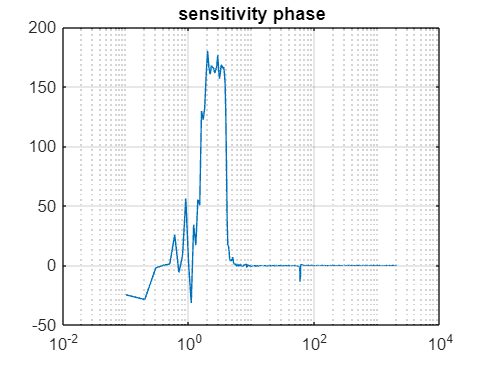


figure()
semilogx(F,angle(S)/pi*180)
title('sensitivity phase')
grid on; hold off

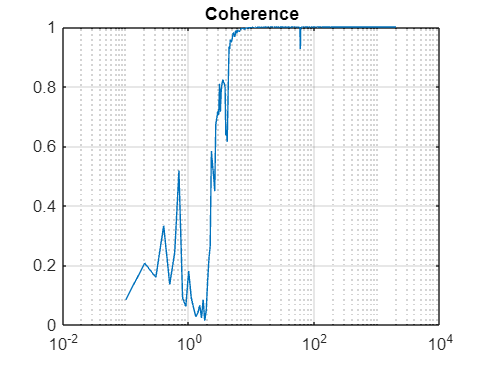

%plotting coherence 
figure()
[coherence_ry, f] = mscohere(d,u,hann(nfft),n_overlap,nfft,fs);
semilogx(f,abs(coherence_ry))
title('Coherence')
grid on; hold off

%plotting open loop transfer function
k = 0.2

k = 0.2000

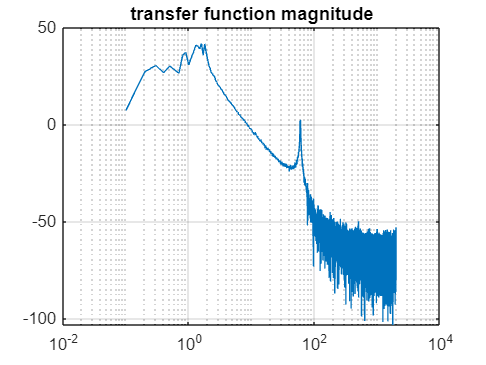

L = (1/k)*(1./S - 1);
figure()
semilogx(F,mag2db(abs(L)))
title('transfer function magnitude')
grid on; hold off

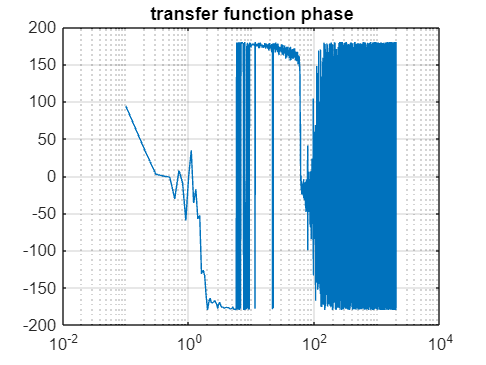


figure()
semilogx(F,angle(L)/pi*180)
title('transfer function phase')
grid on; hold off